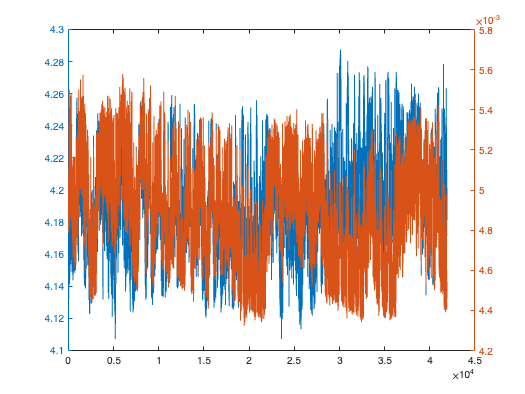



lifetime_histograms_all_dark = lifetime_histograms_all(:,dark_acqs);

coeff = pca(lifetime_histograms_all_dark);

figure
yyaxis left
plot(tau_empTrunc_all_darkonly)
yyaxis right
plot(coeff(:,1))

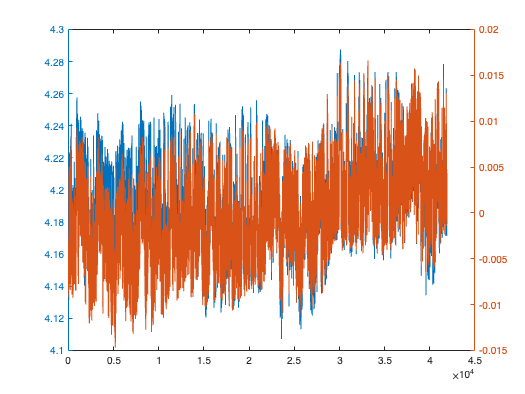


figure
yyaxis left
plot(tau_empTrunc_all_darkonly)
yyaxis right
plot(coeff(:,2))

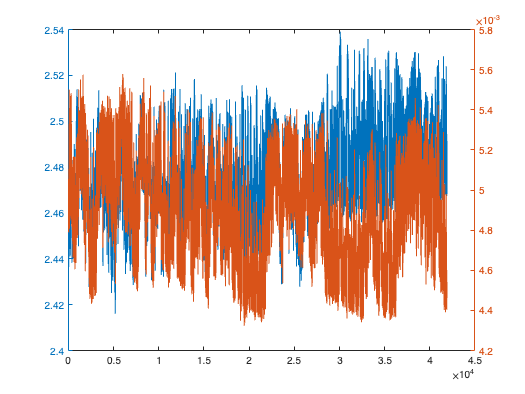


figure
yyaxis left
plot(tau_avg_all_darkonly)
yyaxis right
plot(coeff(:,1))

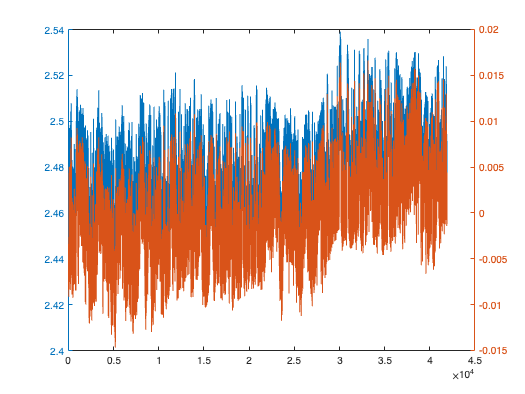


figure
yyaxis left
plot(tau_avg_all_darkonly)
yyaxis right
plot(coeff(:,2))

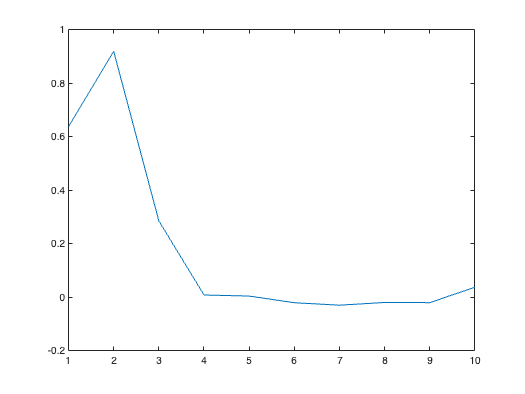


R_all_1=[];


for i=1:10
    R=corrcoef(tau_empTrunc_all_darkonly,coeff(:,i));
    R_all_1=[R_all_1 R(1,2)];
end

figure
plot(R_all_1)

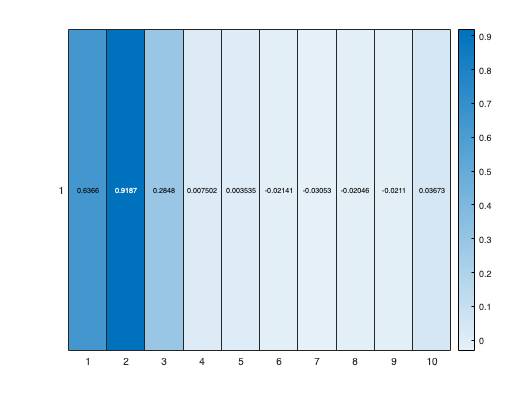


figure
heatmap(R_all_1)

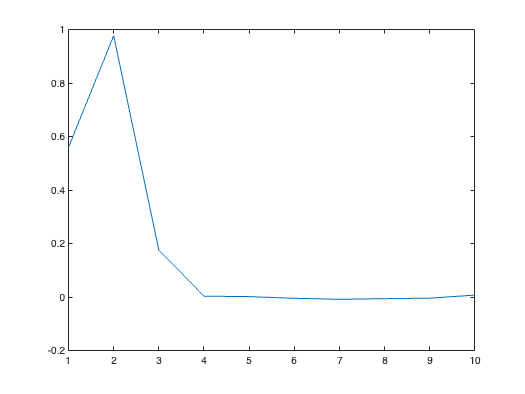


R_all_2=[];


for i=1:10
    R=corrcoef(tau_avg_all_darkonly,coeff(:,i));
    R_all_2=[R_all_2 R(1,2)];
end

figure
plot(R_all_2)

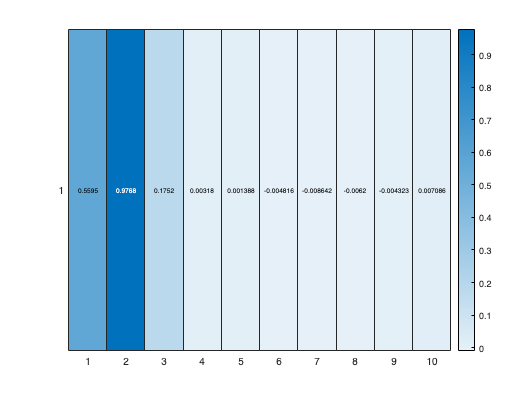


figure
heatmap(R_all_2)

% load FLP_analysis.mat from 1610_001
load('/Volumes/PcSSDA/20220214_1610_SW_001/FLP_analysis.mat');
tau_emp_1610_001=tau_empTrunc_all_darkonly;
tau_avg_1610_001=tau_avg_all_darkonly;
lifetime_histograms_all_dark_1610_001=lifetime_histograms_all(:,dark_acqs);

% load FLP_analysis.mat from 1610_002
load('/Volumes/PcSSDA/20220219_1610_SW_002/FLP_analysis.mat');
tau_emp_1610_002=tau_empTrunc_all_darkonly;
tau_avg_1610_002=tau_avg_all_darkonly;
lifetime_histograms_all_dark_1610_002=lifetime_histograms_all(:,dark_acqs);

% load FLP_analysis.mat from 1610_003
load('/Volumes/PcSSDA/20220314_1610_SW_003/FLP_analysis.mat');
tau_emp_1610_003=tau_empTrunc_all_darkonly;
tau_avg_1610_003=tau_avg_all_darkonly;
lifetime_histograms_all_dark_1610_003=lifetime_histograms_all(:,dark_acqs);


tau_emp_1610=[tau_emp_1610_001;tau_emp_1610_002;tau_emp_1610_003];
tau_avg_1610=[tau_avg_1610_001;tau_avg_1610_002;tau_avg_1610_003];

lifetime_histograms_all_dark_1610=[lifetime_histograms_all_dark_1610_001 lifetime_histograms_all_dark_1610_002 lifetime_histograms_all_dark_1610_003];

photon_counts_all=[];
peak_counts_all=[];

for i=1:size(lifetime_histograms_all_dark_1610,2)
    photon_count=sum(lifetime_histograms_all_dark_1610(:,i));
    photon_counts_all=[photon_counts_all photon_count];

    peak_count=max(lifetime_histograms_all_dark_1610(:,i));
    peak_counts_all=[peak_counts_all peak_count];
end
lifetime_histograms_all_dark_1610_norm1=lifetime_histograms_all_dark_1610./photon_counts_all;
lifetime_histograms_all_dark_1610_norm2=lifetime_histograms_all_dark_1610./peak_counts_all;


coeff_1610=pca(lifetime_histograms_all_dark_1610);

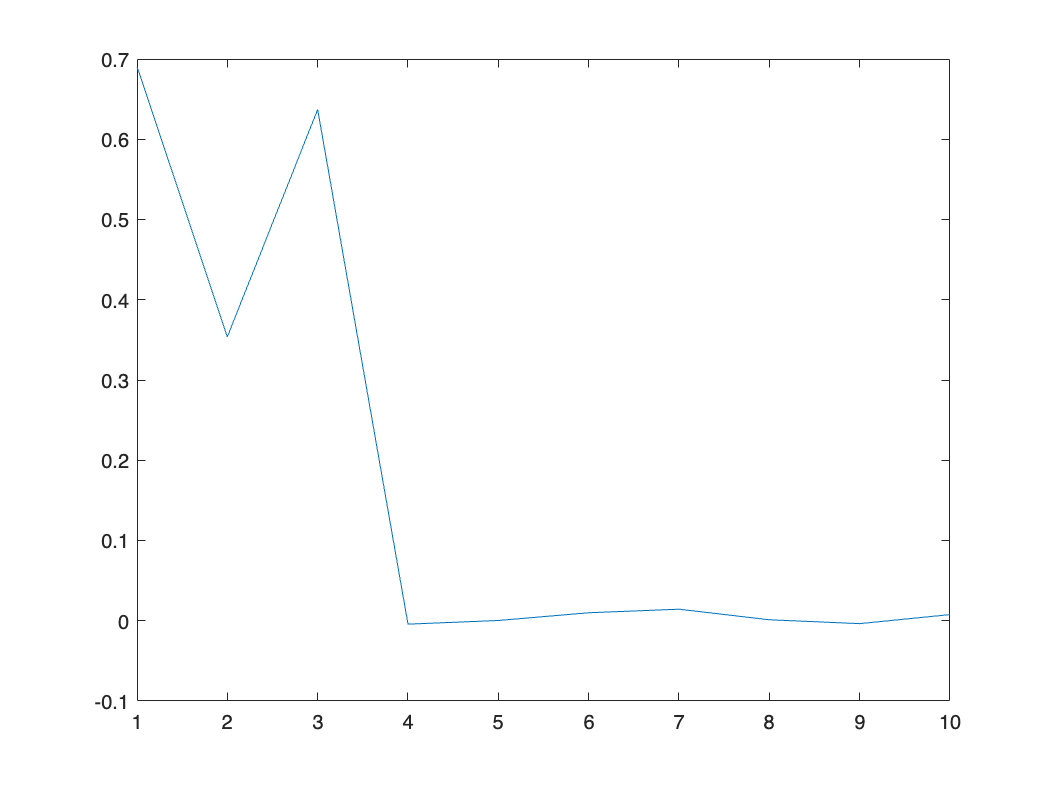



R_all_1=[];


for i=1:10
    R=corrcoef(tau_emp_1610,coeff_1610(:,i));
    R_all_1=[R_all_1 R(1,2)];
end

figure
plot(R_all_1)

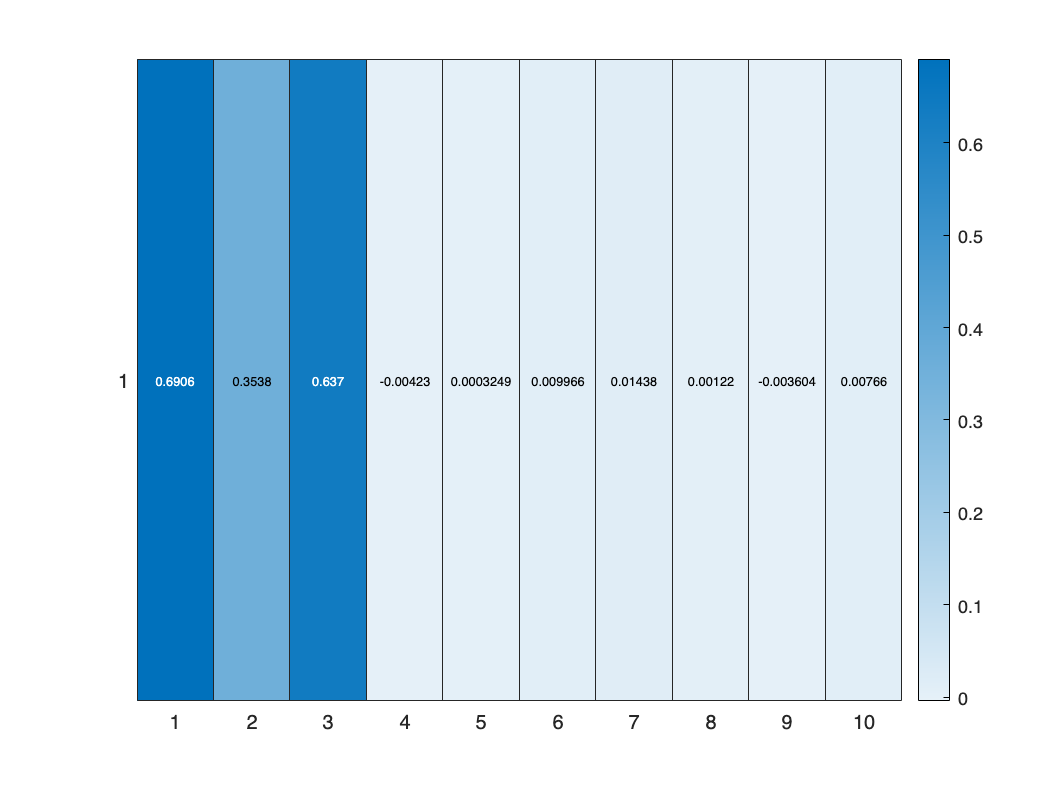


figure
heatmap(R_all_1)

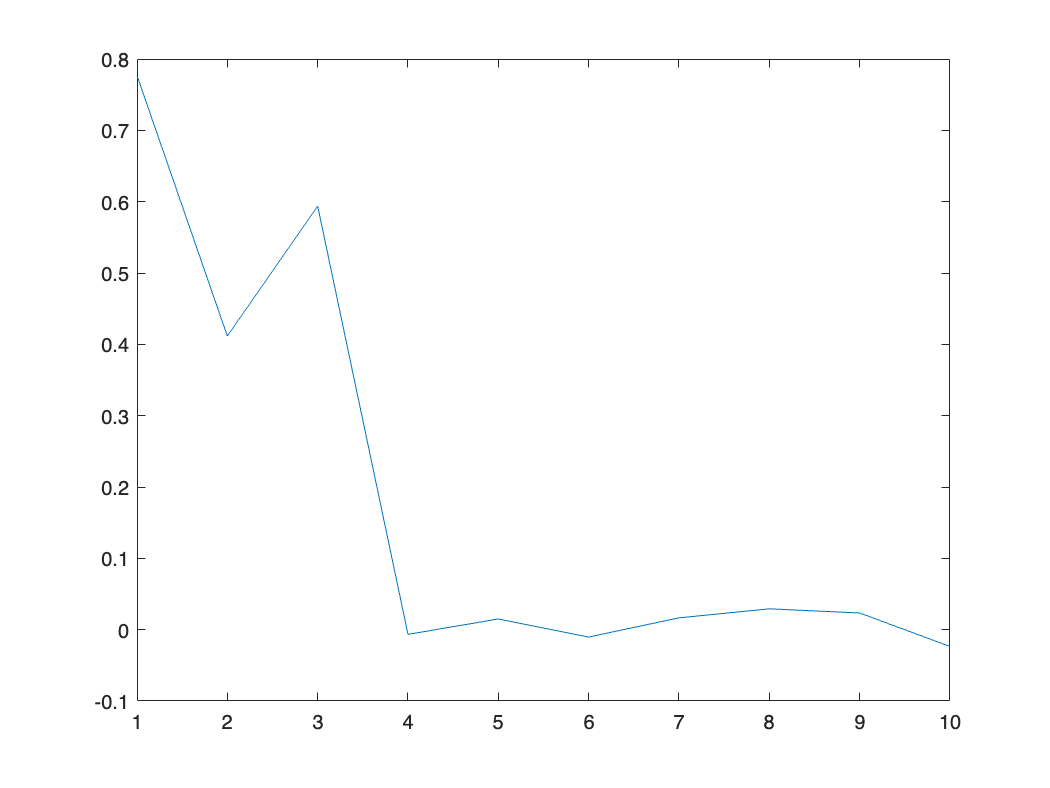


R_all_2=[];


for i=1:10
    R=corrcoef(tau_avg_1610,coeff_1610(:,i));
    R_all_2=[R_all_2 R(1,2)];
end

figure
plot(R_all_2)

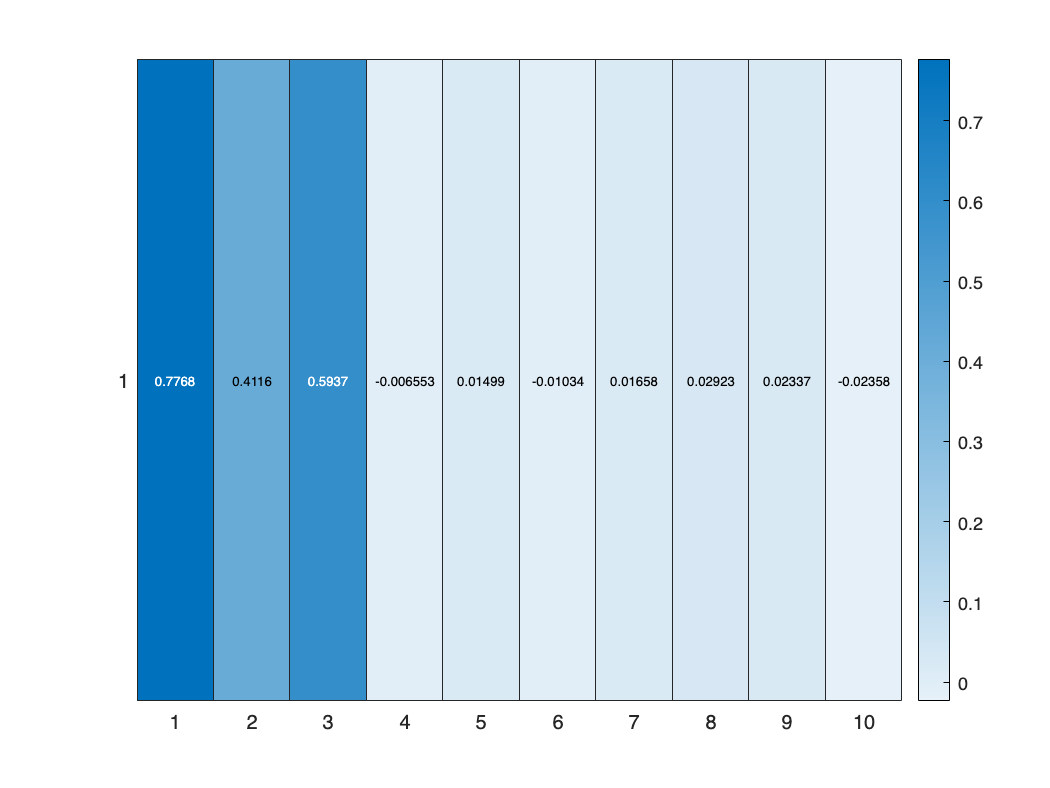


figure
heatmap(R_all_2)

count1=size(tau_avg_1610_001,1)

count1 = 41909

count2=size(tau_avg_1610_001,1)+size(tau_avg_1610_002,1)

count2 = 80767


coeff_1610_001=coeff_1610(1:count1,1);
coeff_1610_002=coeff_1610(count1+1:count2,1);
coeff_1610_003=coeff_1610(count2+1:end,1);


coeff_1610=pca(lifetime_histograms_all_dark_1610_norm1);

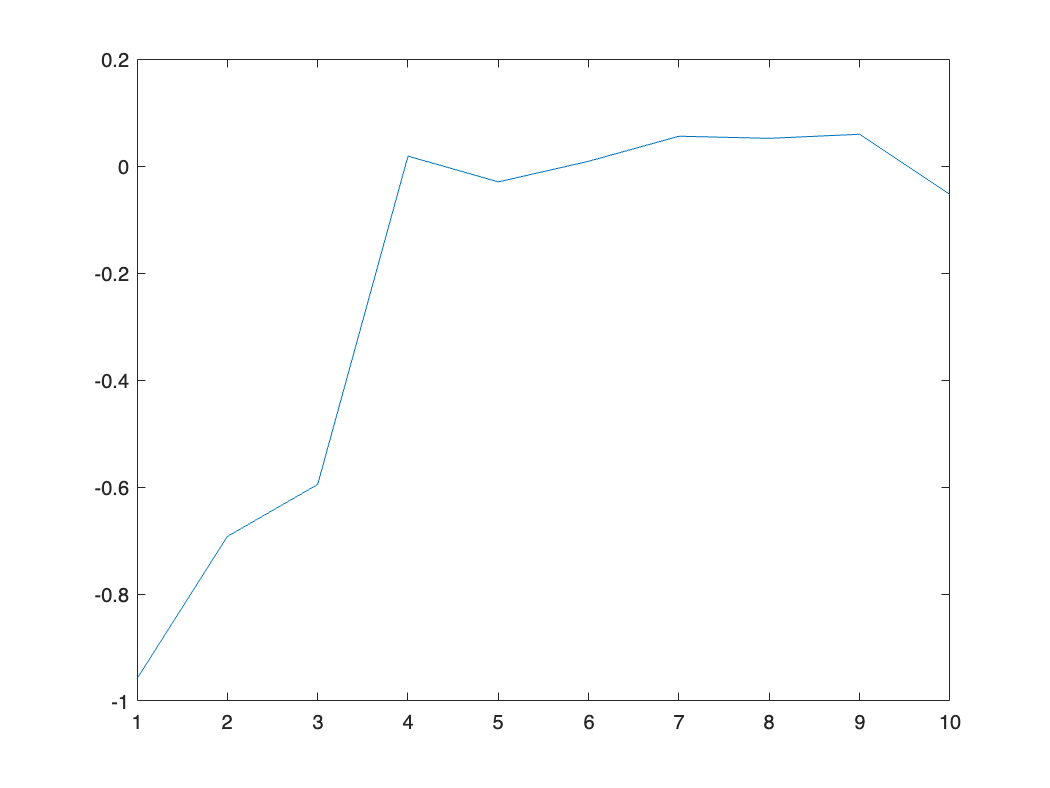



R_all_1=[];


for i=1:10
    R=corrcoef(tau_emp_1610,coeff_1610(:,i));
    R_all_1=[R_all_1 R(1,2)];
end

figure
plot(R_all_1)

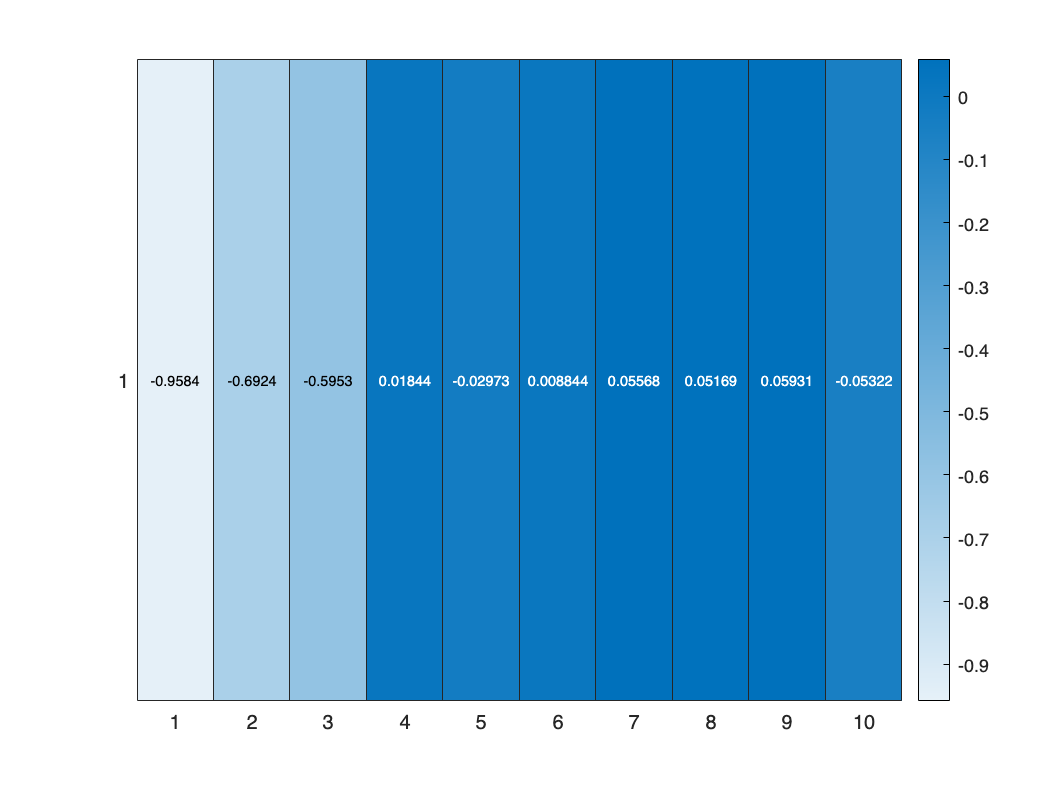


figure
heatmap(R_all_1)

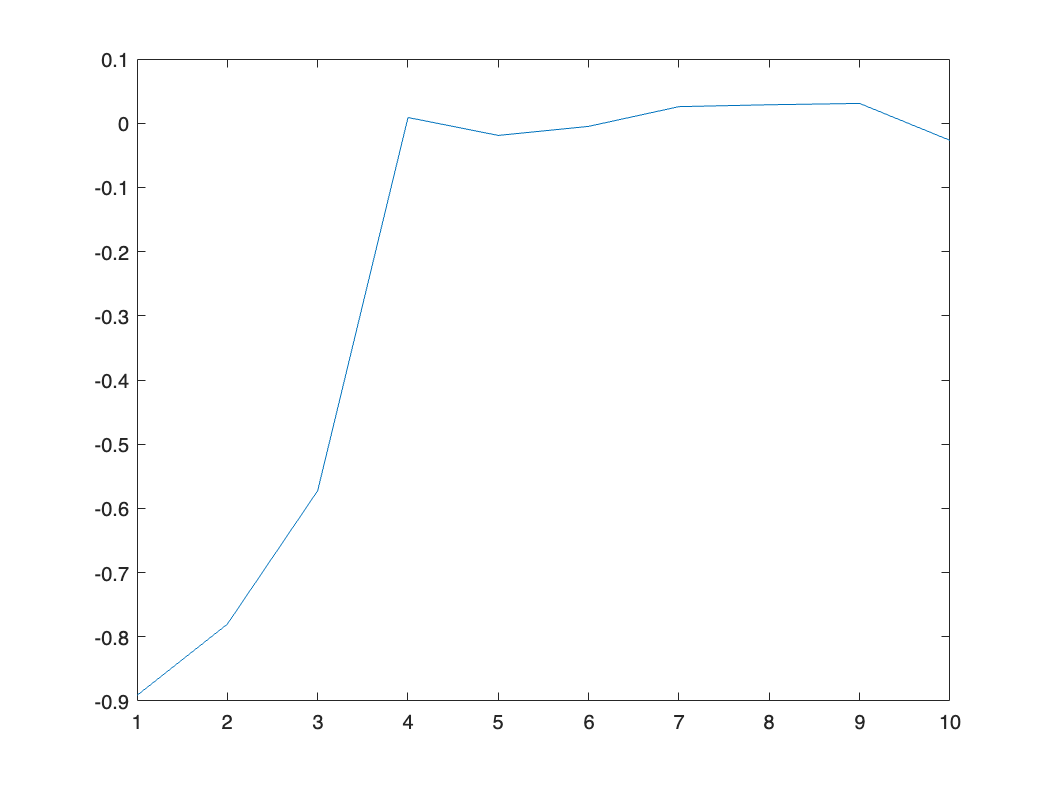


R_all_2=[];


for i=1:10
    R=corrcoef(tau_avg_1610,coeff_1610(:,i));
    R_all_2=[R_all_2 R(1,2)];
end

figure
plot(R_all_2)

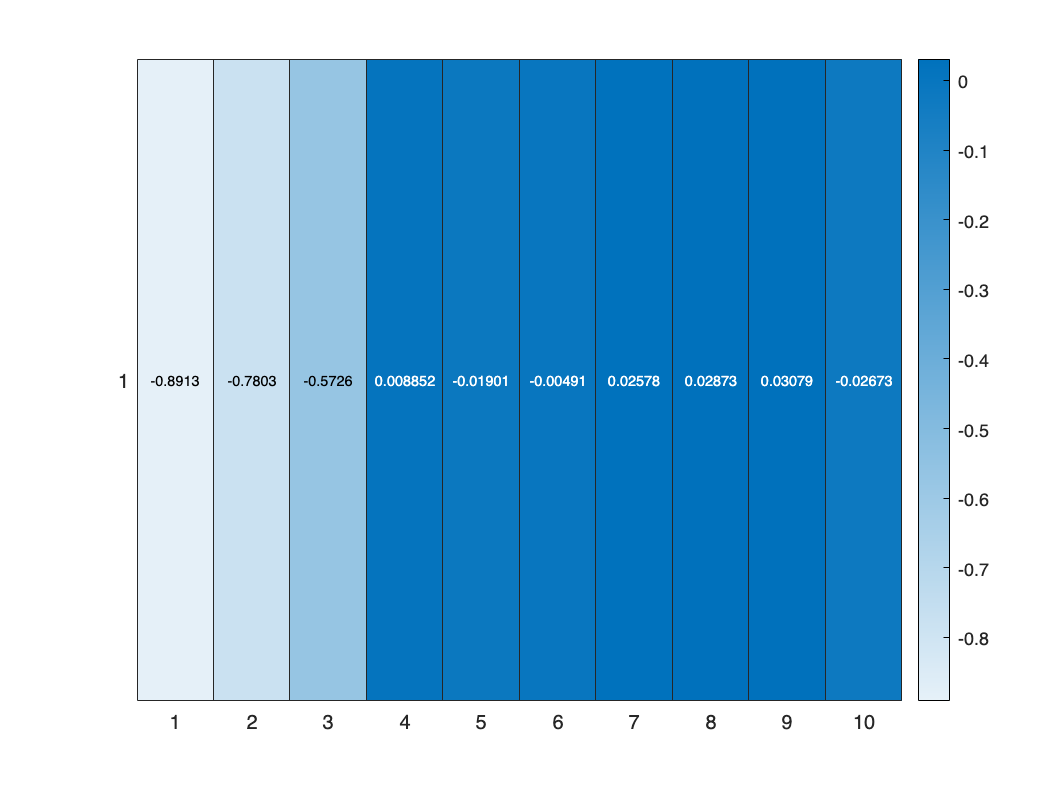


figure
heatmap(R_all_2)

count1=size(tau_avg_1610_001,1)

count1 =        41909


count2=size(tau_avg_1610_001,1)+size(tau_avg_1610_002,1)

count2 =        80767



coeff_1610_001=coeff_1610(1:count1,1);
coeff_1610_002=coeff_1610(count1+1:count2,1);
coeff_1610_003=coeff_1610(count2+1:end,1);


coeff_1610=pca(lifetime_histograms_all_dark_1610_norm2);

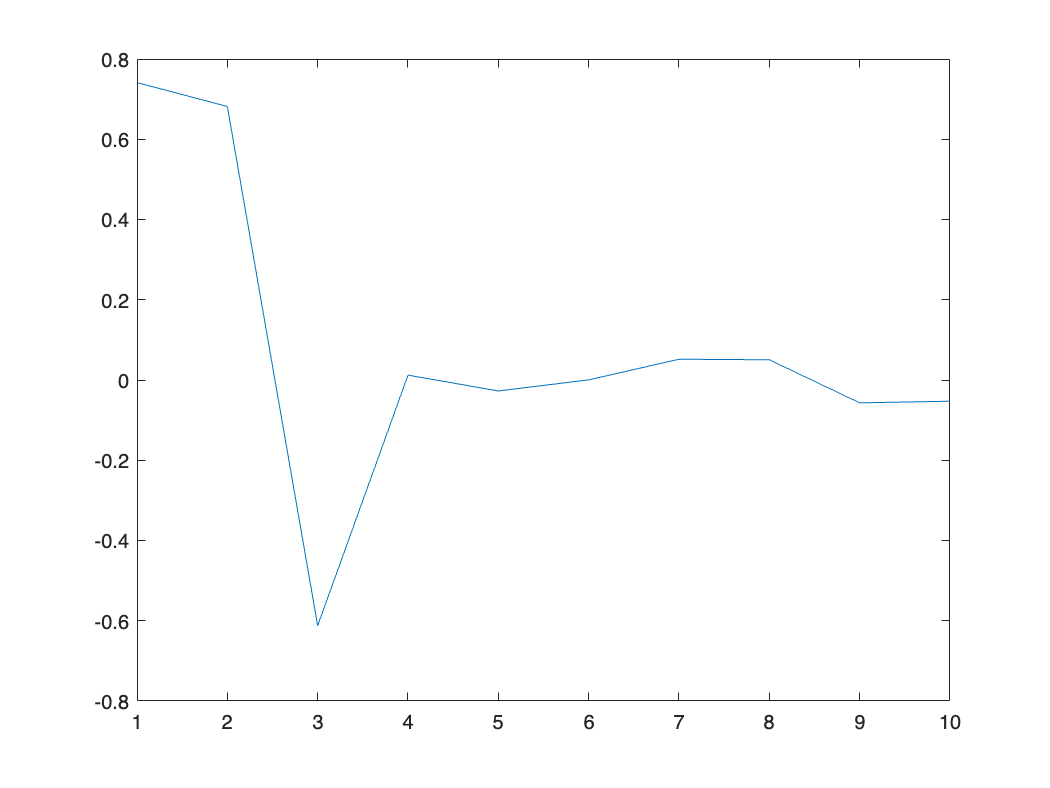



R_all_1=[];


for i=1:10
    R=corrcoef(tau_emp_1610,coeff_1610(:,i));
    R_all_1=[R_all_1 R(1,2)];
end

figure
plot(R_all_1)

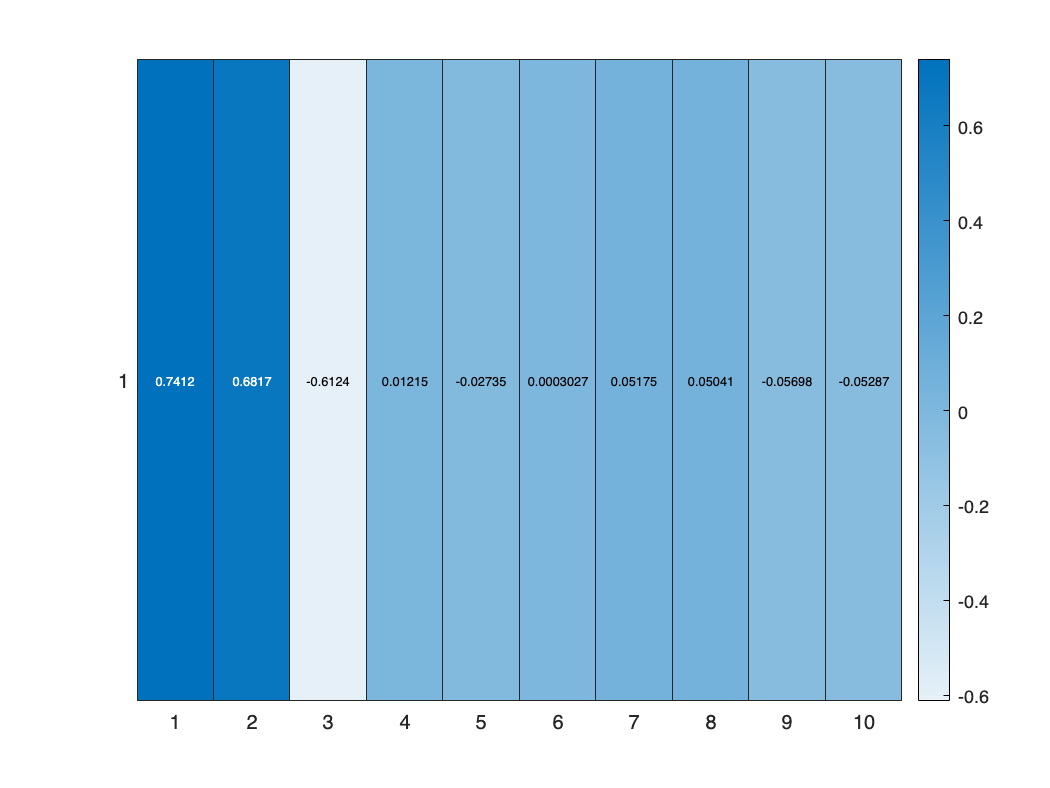


figure
heatmap(R_all_1)

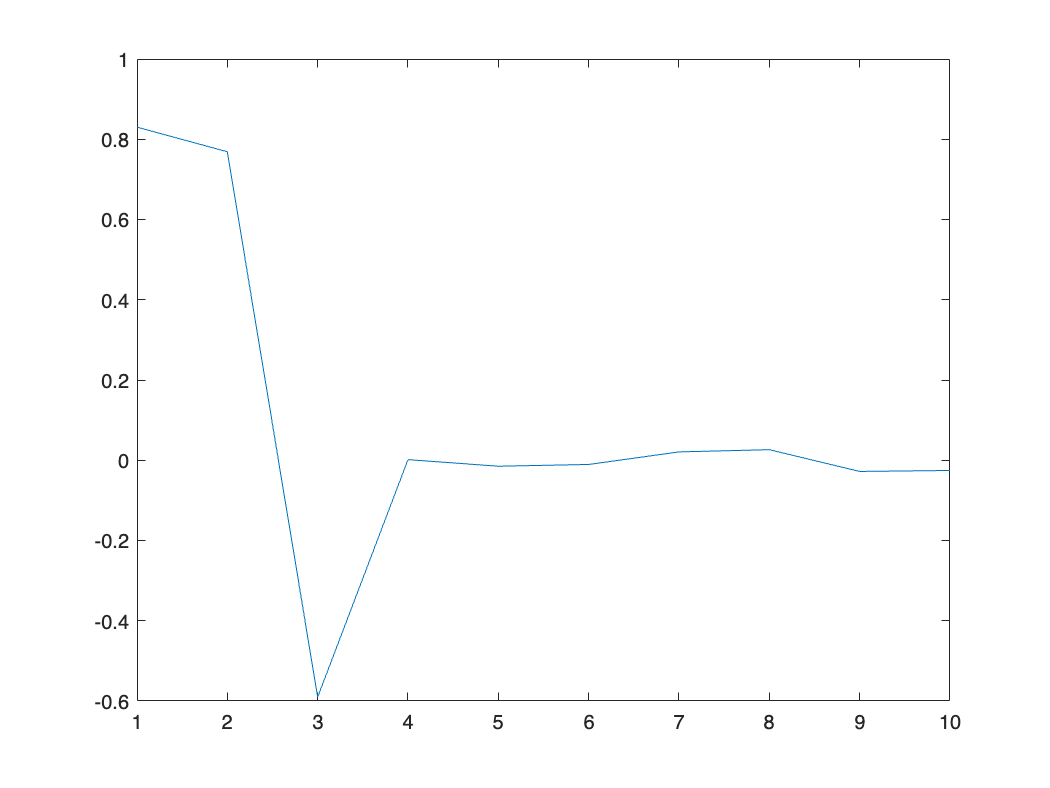


R_all_2=[];


for i=1:10
    R=corrcoef(tau_avg_1610,coeff_1610(:,i));
    R_all_2=[R_all_2 R(1,2)];
end

figure
plot(R_all_2)

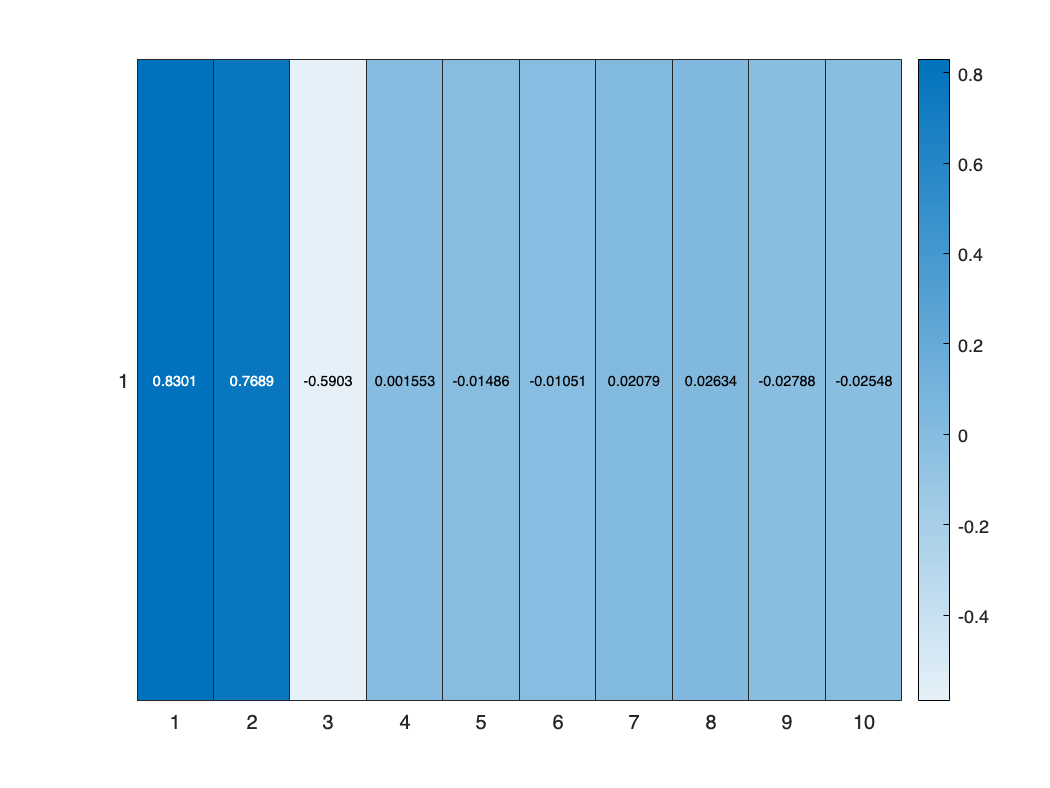


figure
heatmap(R_all_2)

count1=size(tau_avg_1610_001,1)

count1 =        41909


count2=size(tau_avg_1610_001,1)+size(tau_avg_1610_002,1)

count2 =        80767



coeff_1610_001=coeff_1610(1:count1,2);
coeff_1610_002=coeff_1610(count1+1:count2,2);
coeff_1610_003=coeff_1610(count2+1:end,2);

